# Using machine learning to classify face vs house with average  activation in 4 brain regions

This notebook builds on the data that we looked at using brainViewer.mlx (https://drive.google.com/file/d/1iyokKsLVGwjZsU2Vdpo3O9HzcW_XQw5v/view?usp=sharing). 

We'll plot the data in a few ways to understand what goes into the machine learning algorithm.

## The dataset

Haxby, J. V., Gobbini, M. I., Furey, M. L., Ishai, A., Schouten, J. L., & Pietrini, P. (2001). Distributed and overlapping representations of faces and objects in ventral temporal cortex. *Science*, *293*(5539), 2425-2430.

This article provides a dataset that we'll be using for our analysis. This was a really important paper in the early days of people using machine learning on fMRI data. Here's the abstract:

"The functional architecture of the object vision pathway in the human brain was investigated using functional magnetic resonance imaging to measure patterns of response in ventral temporal cortex while subjects viewed faces, cats, five categories of man-made objects, and nonsense pictures. A distinct pattern of response was found for each stimulus category. The distinctiveness of the response to a given category was not due simply to the regions that responded maximally to that category, because the category being viewed also could be identified on the basis of the pattern of response when those regions were excluded from the analysis. Patterns of response that discriminated among all categories were found even within cortical regions that responded maximally to only one category. These results indicate that the representations of faces and objects in ventral temporal cortex are widely distributed and overlapping."

The abstract above explain that they could see patterns that could classify different image types in multiple brain regions, which helped shift our understanding about how objects are processed by our brains. In this assignment, we'll only look at the activation in 4 brain regions overall, but later we will extend this to look at the activation in multiple voxels (like they did in this paper). 

Load the training data.

Data set: [https://drive.google.com/file/d/1DvNboFkDHydQy-uCqv6M0zQnj7r1LMei/view?usp=sharing](https://drive.google.com/file/d/1DvNboFkDHydQy-uCqv6M0zQnj7r1LMei/view?usp=sharing) 

load('s02facehouse4regionsTrain.mat')

This is a table with values for the four regions (you can plot these regions using the masks).

Make the same plot that we ended with last time. But now we'll make them 4 separate plots

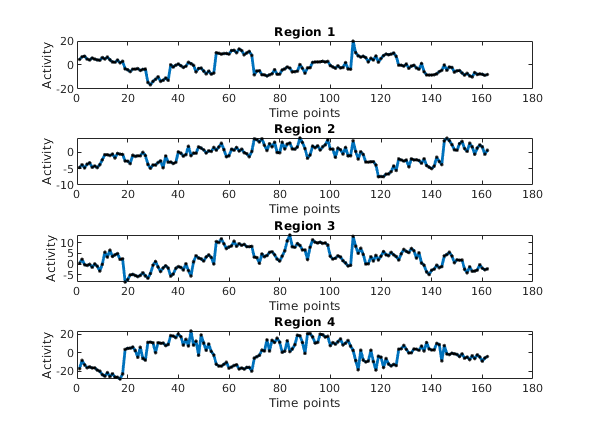

numregions =4;
x = 1:height(train_4regions); % Number of time points
figure
for r =1:4
    subplot(numregions,1,r)
    plot(x,eval(strcat('train_4regions.r',num2str(r),'avg')),'-','LineWidth',2);hold on;
    plot(x,eval(strcat('train_4regions.r',num2str(r),'avg')),'k.','LineWidth',2);hold off;
    title(strcat("Region ",num2str(r))); xlabel('Time points'); ylabel('Activity')
end

Repeat the same thing, but make them 

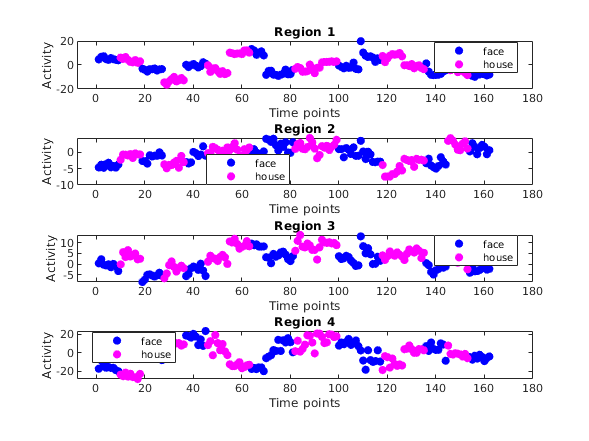

numregions =4;
x = 1:height(train_4regions); % Number of time points
figure
for r =1:4
    subplot(numregions,1,r)
    gscatter(x,eval(strcat('train_4regions.r',num2str(r),'avg')),train_labels,'bm',".",20)
    title(strcat("Region ",num2str(r))); xlabel('Time points'); ylabel('Activity')
end

Now we can take 2 of these plots and plot their y-axes against each other, since their x-axes are the same and not interesting.

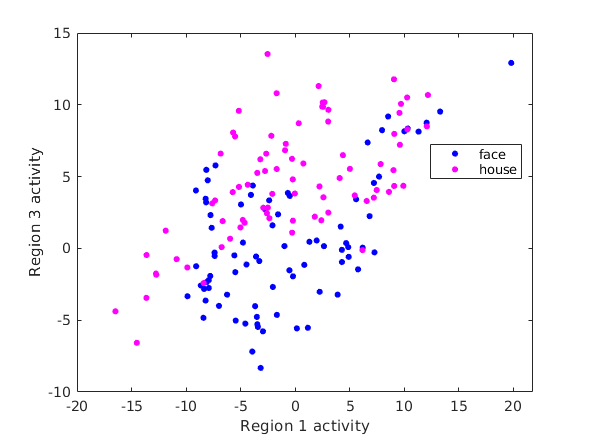

figure
ax1 = 1; ax2 = 3; %Which regions to plot
gscatter(eval(strcat('train_4regions.r',num2str(ax1),'avg')),...
    eval(strcat('train_4regions.r',num2str(ax2),'avg')),...
    train_labels,'bm',".",15)
xlabel(strcat("Region ",num2str(ax1), " activity")); ylabel(strcat("Region ",num2str(ax2), " activity"));

## How to do classification of face vs house with Classification Learner

Matlab provides a graphical user interface (GUI, or gooey) called the Classification Learner app. It can be found under Apps (at the top of Matlab). You might need to look under the category of Machine Learning and Deep Learing, depending on how many aps you have installed. 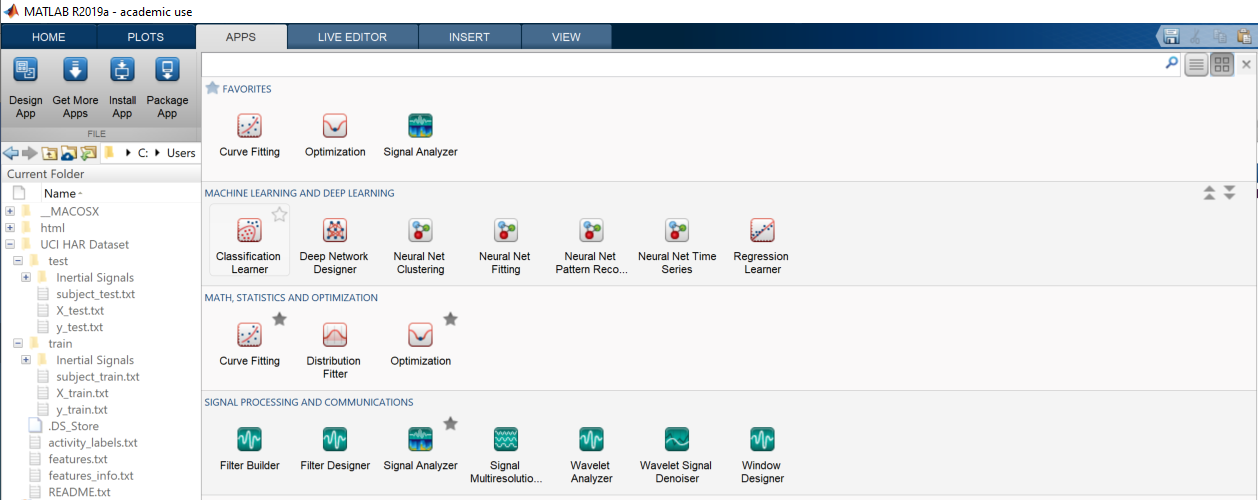

Or you can open this by just calling classificationLearner command. 

classificationLearner

 We will walk through using this GUI to classify whether someone was looking at a face or a house.

Here's some things we will look at:

- Feature selection and plots with 1 feature at a time, with a linear classifier (LDA or linear SVM)

- Feature selection and plots with 2 features, with a linear classifier (LDA or linear SVM)

- Ways to look at results (confusion matrix, ROC curve, etc)

Matlab also posted a video about how to use the classifation learner app with some accelerometer and gyro data. The classification learner video (Machine Learning Made Easy: [https://www.mathworks.com/videos/machine-learning-with-matlab-100694.html)](https://www.mathworks.com/videos/machine-learning-with-matlab-100694.html)) shows some of the features that you can work with using the Classification Learner App. You don't need to watch this, it's intended to be a back-up reference.

## Assignment

Your assignment is to use this data set (train_4regions and train_lables) to perform classification on whether a person was looking at a face or a house. Please take a little time to explore different classification algorithms and parameters to help you build intuition about what effects different settings have and to practice interpreting results.  You can do this using the classification learner app or Matlab code (see below).

**Use "No Validation" when you set up your session**, so that we have consistent results across people.

Try to get the highest classification accuracy possible and to find an algorithm that you think will work well.

Share you results from at least 3 different configurations in the spreadsheet linked below.

- Use columns B-F to indicate which brain regions you included (R1-R4) and/or a description of any other feature you used (for example you can make new features by altering or combining date... FeatureX = log(r1avg), or FeatureY = r1avg * r2avg.... you can get creative here if you're feeling saucy). 

- Use columns G-H to describe the model that you used (the name of the algorithm and what parameters you used). You can click on the "advanced" button to tweak the default parameters of any algorithm).

- Use columns I-K to describe the results.

- Use column L to indicate which one had the highest accuracy and which one you think might perform best on new data (these might be the same). You can also capture any other comments in column M.

High praise (and maybe even a prize) will go to the people with the highest accuracy on the training and the test sets. 

[https://docs.google.com/spreadsheets/d/1nrHxIqBlNek8qRqsZTYmTq4CEx72nYwwHX8vVaAshDE/edit?usp=sharing](https://docs.google.com/spreadsheets/d/1nrHxIqBlNek8qRqsZTYmTq4CEx72nYwwHX8vVaAshDE/edit?usp=sharing)

## Optional: Setup and run classification on the training data (using code)

This code sets up and runs the classification on the training data. 

% Predictors are features (sometimes matlab uses the word predictors
% instead, so we're matching their language (which will make looking up
% help easier).

predictorNames = train_4regions.Properties.VariableNames; 
predictors = train_4regions(:,predictorNames); %This is the data for these predictorNames
% Note: you could use a different version of predictorNames to choose a
% subset of the features.


% Response is the labels, just putting this in a separate variable to match
% the matlab documentation
response = train_labels; %labels


The lines below build the classifier. You can look up the different parameters you can put into the fitcsvm function, these include things like: 'OutlierFraction',0.10,...

Or you might want to look up other classifiers besides SVM to use here. Matlab has lots of options, which have different parameters, but tend to take in the same form of predictors and response variables.

% This is the code that sets up the SVM classifier
trainedClassifier = fitcsvm(predictors, ...
    response, ...
    'KernelFunction', 'Linear', ...
    'Standardize',false...  
     );  % 

fieldnames(trainedClassifier)

ans = 34×1 cell array
    {'BoxConstraints'                   }
    {'CacheInfo'                        }
    {'ConvergenceInfo'                  }
    {'Gradient'                         }
    {'IsSupportVector'                  }
    {'Nu'                               }
    {'NumIterations'                    }
    {'OutlierFraction'                  }
    {'ShrinkagePeriod'                  }
    {'Solver'                           }
    {'Y'                                }
    {'X'                                }
    {'RowsUsed'                         }
    {'W'                                }
    {'ModelParameters'                  }
    {'NumObservations'                  }
    {'BinEdges'                         }
    {'HyperparameterOptimizationResults'}
    {'PredictorNames'                   }
    {'CategoricalPredictors'            }
    {'ResponseName'                     }
    {'ExpandedPredictorNames'           }
    {'ClassNames'                       }
    {'Prior'

Then we predict what the results are for our same data (predictors) using our model. We know this will over-estimate how well our model will work on other data, but we can use this as a starting place.

predictions = trainedClassifier.predict(predictors);
accuracy = sum(predictions==train_labels)./height(train_labels)

accuracy = 0.7531

You can make a confusion chart using the code below (there are different parameters depending on how you normalize).

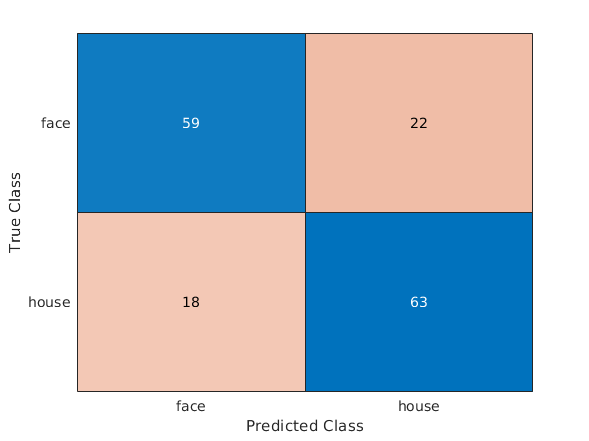

trainconchart = confusionchart(train_labels,predictions);

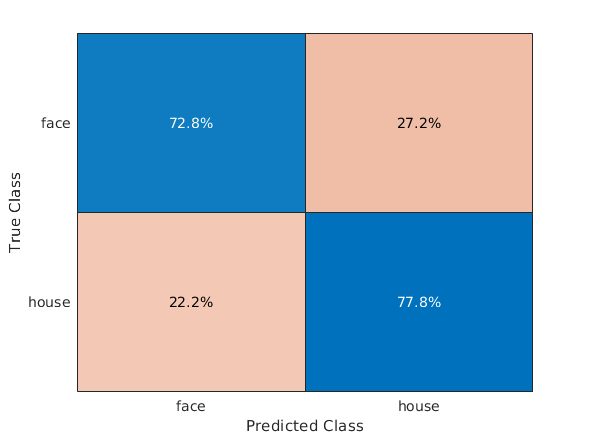

trainconchartNorm = confusionchart(train_labels,predictions,'Normalization','row-normalized');